clear all
close all
clc

x = -2:0.1:4;
y = -2:0.1:4;
[x,y] = meshgrid(x,y);
z = (x-1).^2+(y-1).^2;
x0 = -2;
y0 = 4;
EPS = 0.00001;  %error limit
px = 0.04;      %x step size
py = 0.02;      %y step size
point = Tidu(x0,y0,EPS,px,py);


x = 1.0000

y = 1.0107

n = 139

point =    -2.0000    4.0000   18.0000
   -1.7600    3.8800   15.9120
   -1.5392    3.7648   14.0917
   -1.3361    3.6542   12.5020
   -1.1492    3.5480   11.1115
   -0.9772    3.4461    9.8930
   -0.8191    3.3483    8.8234
   -0.6735    3.2543    7.8828
   -0.5397    3.1642    7.0542
   -0.4165    3.0776    6.3229


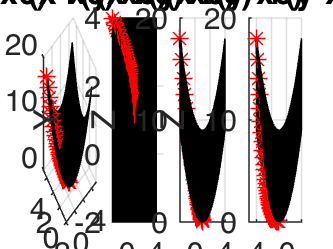

figure
subplot(141)
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("(x-x0)^2+(y-x0)^2")

subplot(142)
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("(x-x0)^2+(y-x0)^2")
view(0,90)

subplot(143)
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("(x-x0)^2+(y-x0)^2")
view(0,0)

subplot(144)
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("(x-x0)^2+(y-x0)^2")
view(-90,0)


zo=zeros((size(point,1)-size(z,1)),size(z,2));
data12=[point,[x;zo],[y;zo],[z;zo]];
csvwrite('data12.csv',data12);


function point = Tidu(x,y,EPS,px,py)
    syms xx yy
    fun = (xx-1)^2+(yy-1)^2;
    dfunx = 2*xx-2;
    dfuny = 2*yy-2;
    a = eval(subs(fun,[xx,yy],[x,y]));
    b = a+1;
    n=1;
    point(n,:) = [x y a];
    while (abs(a-b) >= EPS)
      a = eval(subs(fun,[xx,yy],[x,y]));
      x = x - px*eval(subs(dfunx,xx,x));
      y = y - py*eval(subs(dfuny,yy,y));
      b = eval(subs(fun,[xx,yy],[x,y]));
      n = n+1;
      point(n,:) = [x y b];
    end
end